x0 = [2.5320,2.6470,2.6290,2.5840,2.6090,2.6010,2.5280,2.5630,2.6540,2.6190];
n = length(x0);

%灰度模型部分
me = quantile(x0,0.5);
[h,p,stat] = runstest(x0,me)%游程检验  h=0不拒绝原假设，是随机的

h = 0

p = 1

stat = 包含以下字段的 struct :
    nruns: 6
       n1: 5
       n0: 5
        z: 0



x1 = cumsum(x0);   %累加序列
zk = (x1(1:end-1)+x1(2:end))/2

zk =     3.8555    6.4935    9.1000   11.6965   14.3015   16.8660   19.4115   22.0200   24.6565


B = [-zk',ones(size(zk'))];
yn = x0(2:end)';
ab = B\yn    %ab(1)是a，ab（2）是b

ab =     0.0010
    2.6185



syms x(t)
dsolve_ans = dsolve(diff(x)+ab(1)*x==ab(2),x(0)==x0(1));
y_yuce = subs(dsolve_ans,'t',[0:n+5]);  %求累加序列预测值  多加了六个数
y_yuce = double(y_yuce)

y_yuce =     2.5320    5.1465    7.7584   10.3675   12.9740   15.5778   18.1789   20.7772   23.3730   25.9660   28.5564   31.1440   33.7291   36.3114   38.8911   41.4681


% diff(y_yuce)
y_yuce0 = [x0(1),diff(y_yuce)]%求原始序列的预测值（累加序列推回原始数列可用diff（数字））

y_yuce0 =     2.5320    2.6145    2.6118    2.6092    2.6065    2.6038    2.6011    2.5984    2.5957    2.5930    2.5904    2.5877    2.5850    2.5823    2.5797    2.5770


c = std(y_yuce0(1:n))/std(x0)  %求后验差比值

c = 0.5348


%bootstrap部分
nyuce = (y_yuce0(n+1:end));  %提取后面新加进来的6个预测值
nyb = [x0,nyuce];%将提取的预测值与原来的样本构成新的数据样本来扩充样本
nyb = reshape(nyb,[4,4])  %将新样本分成4个子样本

nyb =     2.5320    2.6090    2.6540    2.5850
    2.6470    2.6010    2.6190    2.5823
    2.6290    2.5280    2.5904    2.5797
    2.5840    2.5630    2.5877    2.5770


mu = mean(nyb)

mu =     2.5980    2.5753    2.6128    2.5810


jc = range(nyb)  %求极差

jc =     0.1150    0.0810    0.0663    0.0080



b =rand(4,1000);
num = floor(b*length(nyb))+1  %把随机数映射为编号,用来做下面抽样的编号

num =      4     2     4     3     2     4     3     1     4     2     3     3     3     3     3     2     2     4     1     4     1     1     4     3     1     1     1     2     4     1     2     4     2     4     4     2     4     4     1     2     1     4     2     1     2     1     3     2     1     2
     4     4     4     1     4     1     4     2     2     2     2     1     4     2     3     2     4     4     1     1     3     3     2     1     2     4     2     3     3     3     1     2     3     1     2     4     4     4     2     1     4     3     3     4     2     3     2     4     2     3
     2     3     1     2     3     2     1     1     4     4     3     3     4     2     3     4     4     3     4     1     4     3     2     2     3     2     4     2     4     4     1     1     4     1     4     2     3     2     2     1     3     3     2     3     4     4     2     2     3     1
     2     1     1     2     3     4     2     1     4     1     2     2     2     2     2 

bb = repmat(nyb',1,1000);  %重复数组副本1000次
bb = bb(num)  %对新序列重复抽样(用num来选取)

bb =     2.5850    2.6090    2.5850    2.6540    2.6090    2.5850    2.6540    2.5320    2.5850    2.6090    2.6540    2.6540    2.6540    2.6540    2.6540    2.6090    2.6090    2.5850    2.5320    2.5850    2.5320    2.5320    2.5850    2.6540    2.5320    2.5320    2.5320    2.6090    2.5850    2.5320    2.6090    2.5850    2.6090    2.5850    2.5850    2.6090    2.5850    2.5850    2.5320    2.6090    2.5320    2.5850    2.6090    2.5320    2.6090    2.5320    2.6540    2.6090    2.5320    2.6090
    2.5850    2.5850    2.5850    2.5320    2.5850    2.5320    2.5850    2.6090    2.6090    2.6090    2.6090    2.5320    2.5850    2.6090    2.6540    2.6090    2.5850    2.5850    2.5320    2.5320    2.6540    2.6540    2.6090    2.5320    2.6090    2.5850    2.6090    2.6540    2.6540    2.6540    2.5320    2.6090    2.6540    2.5320    2.6090    2.5850    2.5850    2.5850    2.6090    2.5320    2.5850    2.6540    2.6540    2.5850    2.6090    2.6540    2.6090    2.5850    2.6090    

mmu = mean(bb)

mmu =     2.5970    2.5950    2.5585    2.6010    2.6255    2.5778    2.5950    2.5513    2.5910    2.5838    2.6315    2.6122    2.6083    2.6202    2.6427    2.5970    2.5778    2.6195    2.5758    2.5453    2.5758    2.6063    2.6030    2.6010    2.6122    2.5838    2.5838    2.6202    2.6023    2.5890    2.5513    2.5838    2.6143    2.5758    2.5970    2.5838    2.5890    2.5778    2.5705    2.5513    2.6063    2.6255    2.6010    2.5890    2.6143    2.5758    2.6143    2.5970    2.5817    2.6010


mjc = range(bb)

mjc =     0.0240    0.1220    0.0530    0.1220    0.0690    0.0770    0.1220    0.0770    0.0240    0.0770    0.0450    0.1220    0.0690    0.0450    0.0450    0.0240    0.0770    0.0690    0.1220    0.0530    0.1220    0.1220    0.0240    0.1220    0.1220    0.0770    0.0770    0.0450    0.0690    0.1220    0.0770    0.0770    0.0690    0.1220    0.0240    0.0770    0.1220    0.0770    0.0770    0.0770    0.1220    0.0690    0.1220    0.1220    0.0690    0.1220    0.0690    0.0240    0.1220    0.1220


mmu = sort(mmu);
mjc = sort(mjc);
alpha = 0.0027;   %3西格玛对应alpha是0.27%
k1 = floor(1000*alpha/2);
k2 = floor(1000*(1-alpha/2));
mqj=[mmu(k1),mmu(k2)]  %均值的置信区间

mqj =     2.5320    2.6540


jqj=[mjc(k1),mjc(k2)]  %极差的置信区间

jqj =          0    0.1220


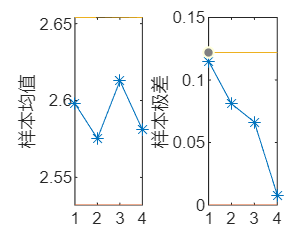


subplot(1,2,1)
plot(mu,'*-')
hold on
plot([1,4],[mqj(1),mqj(1)])
plot([1,4],[mqj(2),mqj(2)])
ylabel('样本均值')
subplot(1,2,2)
plot(jc,'*-')
hold on
plot([1,4],[jqj(1),jqj(1)])
plot([1,4],[jqj(2),jqj(2)])
ylabel('样本极差')